We'll test the conclusion of $O(n^3)$ flops experimentally, using the built-in `lu` function instead of the purely instructive `lufact`.

n_ = (200:100:2400)';
t_ = 0*n_;
for i = 1:length(n_)
    n = n_(i);
    A = randn(n,n);  
    tic  % start a timer
    for j = 1:6,  [L,U] = lu(A);  end
    t = toc;  % read the timer
    t_(i) = t/6;  
end

We plot the performance on a log-log graph and compare it to $O(n^3)$. The result could vary significantly from machine to machine. 

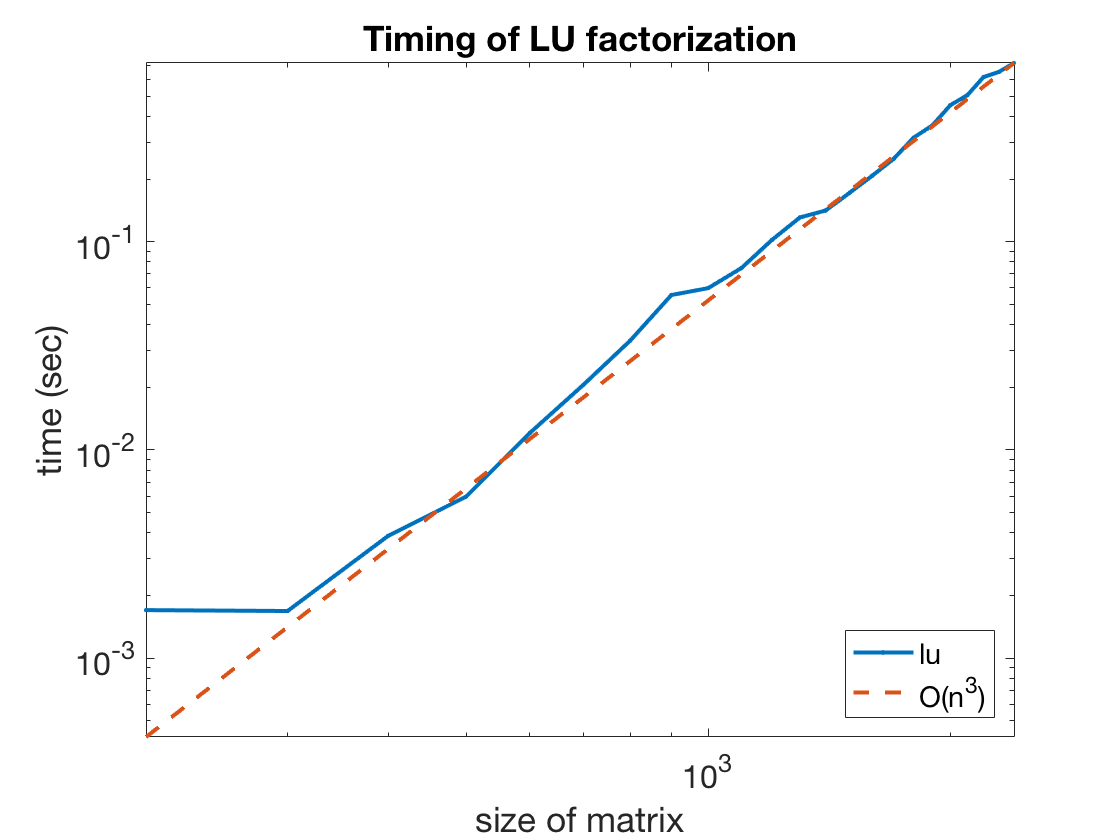

loglog(n_,t_,'.-')
hold on, loglog(n_,t_(end)*(n_/n_(end)).^3,'--')
axis tight
xlabel('size of matrix'), ylabel('time (sec)')
title('Timing of LU factorization')
legend('lu','O(n^3)','location','southeast')